MLO_st.name='MLO'; 
MLO_st.lat=19.5362;
MLO_st.lon=-155.576;
MLO_st.alt=3397;
MLO_st.env='Mt';
MLO_st.footp='Mx';


MLO_rd=read_betsy('mlo_1974_2018',MLO_st.name);

MLO_rd2=read_betsy('mlo_1974_2018_longformat',MLO_st.name);

datevec(MLO_rd.Time(1))

ans =         1974           1          26           0           0           0


datevec(MLO_rd.Time(end))

ans =         2019           1           1           0           0           0


 prctile(MLO_rd.U_S,[5 50 95])

ans =     0.0250    3.7000   17.7750


  prctile(MLO_rd.U0_S,[5 50 95])

ans =          0    6.2500   18.8500


   prctile(MLO_rd.U1_S,[5 50 95])

ans =          0    6.3500   18.8500


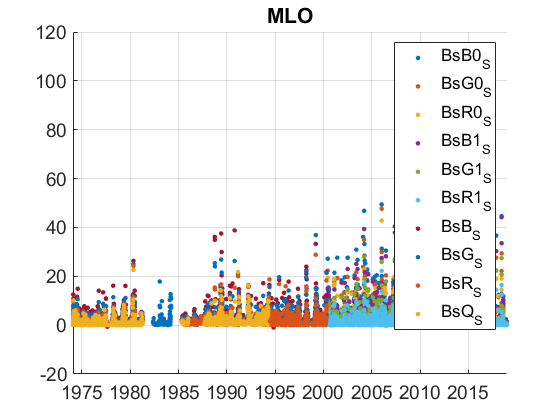

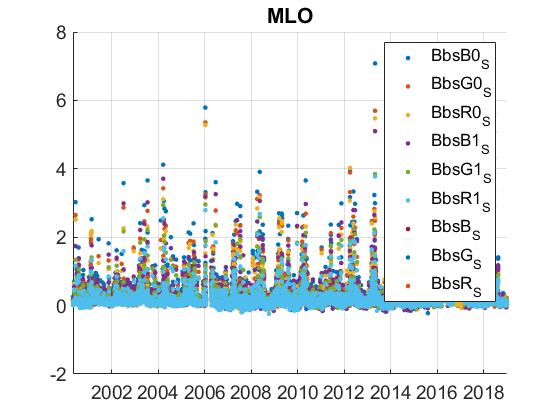

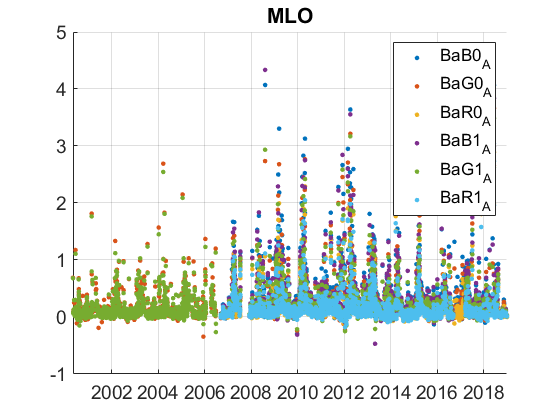

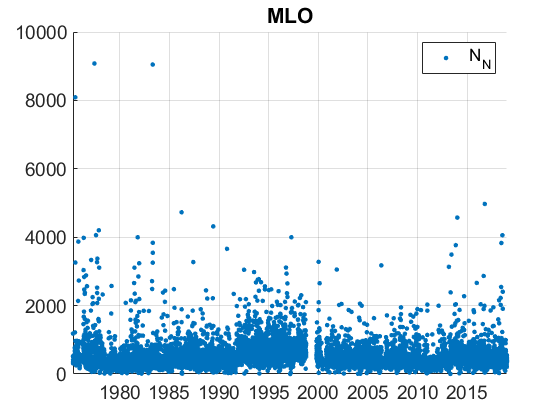

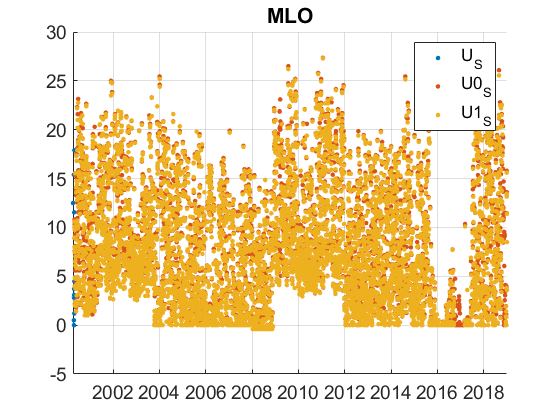

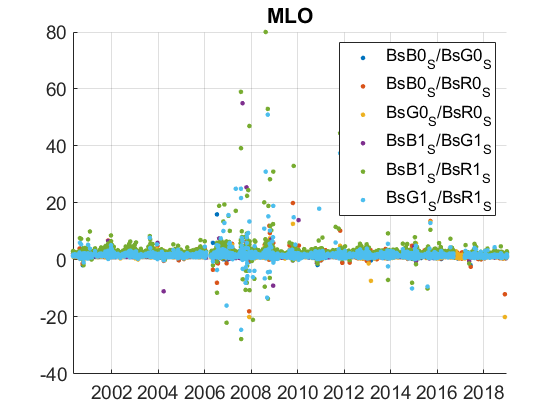

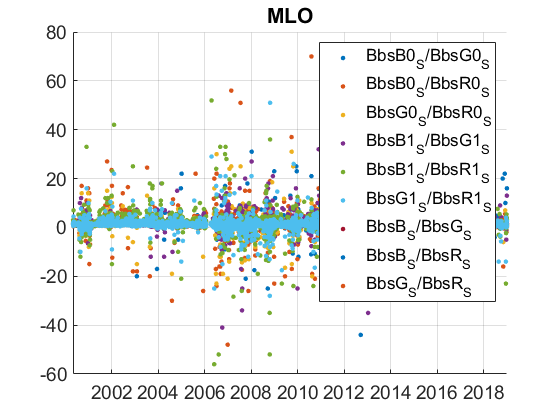

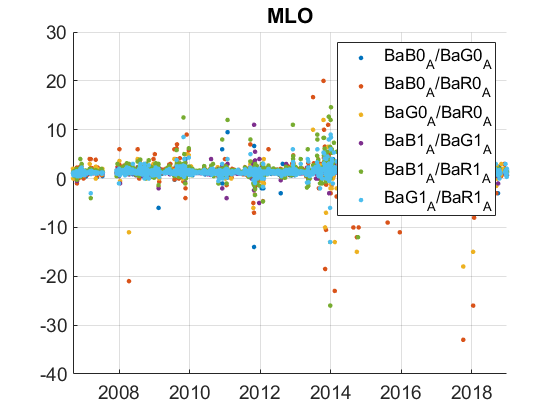

plotFigControl(MLO_rd,MLO_st.name);

% 2 size cut, since 2000
% sc: ok, clear seasonal cycle in summer, 
% abs: 2 size cut,seasonal cycle
%Bs/N and Ba/N: clear seasonal cycle

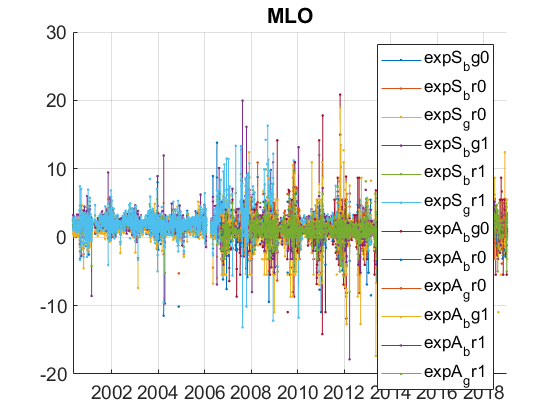

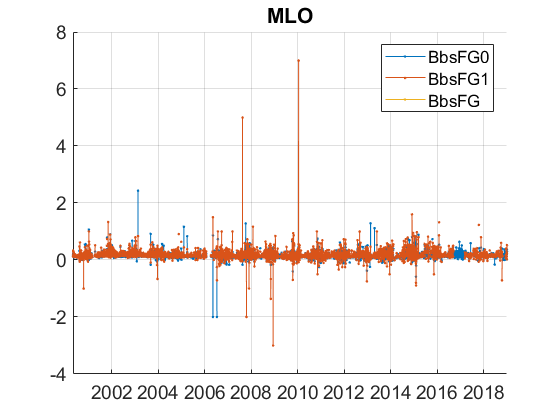

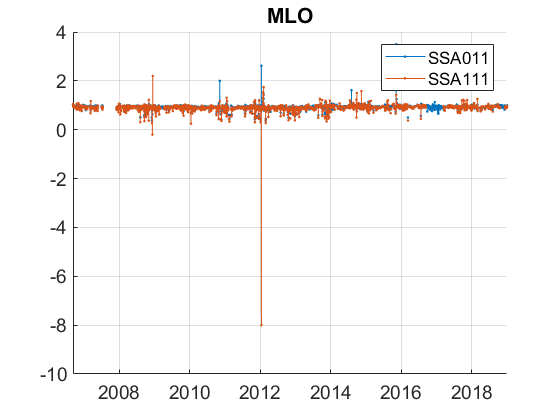

lambdaSC=[450;550;700]*ones(1,4);
lambdaAE=[467;530;660]*ones(1,4);
lambdaAE7=[370 470 520 590 660 880 950];
MLO_cal=compute_exp_SSA(MLO_rd,lambdaSC, lambdaAE3);
plotFigControl_cal(MLO_cal, MLO_st.name);

%Questions:
%problems:
 %scat: what is BsQ_S ?
 %scat minima are lower from 1985 to1995, reason ?
 %scat minima and maxima are lower before 1985
 %scat: strange high data in december 1993-jan 94
 %ratio of scattering is usually lower in 2000 than after
 % all the backscat ratio between several wavelength have less small values and negatives between 2001 and 2006, why ?
 % exp scat seems also to be lower in 2000 than after. More pronounced for PM10 than PM 1. Visible also on the BbsF
 
 %PSAP 1w to 3w change in 2006, the max seems to be lower with 1w.
 % exp =0 and exp= 3.16 seems to be favored
 
 
 %N: rupture in sept 1991, not homogeneous before 1980, strange in 2011

MLO_tr=MLO_rd2;
MLO_tr.y=year(MLO_tr.Time);
% begin at the beginning of a year:1988 for scat, 2001 for backscat and abs
%end: 2018
P=timerange('1988-01-01','2019-01-01');
MLO_tr=MLO_tr(P,:);

%no RH trend and no dry trend
%no backscatt data in the first year (ex BbsB_S)
names=fieldnames(MLO_tr);
c= startsWith(names,["T1";"T0";"T_";"P_";"P1_";"P0_";"N";"U_";"U1";"U0";"BbsB_";"BbsG_";"BbsR_"]) |  contains(names,["Q","dry"]);
N=names(c);
for i=1:length(N)
    MLO_tr.(N{i})=[];
end

names=fieldnames(MLO_tr);
P2=timerange('1988-01-01','2001-01-01');
c=startsWith(names,["Ba";"Bbs"]);
N=names(c);
for i=1:length(N)
    MLO_tr.(N{i})(P2)=NaN;
end 

%Exp Abs since 2007:
P3=timerange('1998-01-01','2007-01-01');
c=startsWith(names,["BaB";"BaR"]);
N=names(c);
for i=1:length(N)
    MLO_tr.(N{i})(P3)=NaN;
end 

% invalidate scat 290 (17 October) 1993 and 117 (27 April) 1994
P4=timerange('1993-10-17','1994-04-27');
c=startsWith(names,["Bs"]);
N=names(c);
for i=1:length(N)
    MLO_tr.(N{i})(P4)=NaN;
end 
%one series with BsB and BsB0 (TSP and PM10)
MLO_tr.BsB0_S11=sum([MLO_tr.BsB_S11 MLO_tr.BsB0_S11],2,'omitnan');
indz=MLO_tr.BsB0_S11==0;
MLO_tr.BsB0_S11(indz)=NaN;
MLO_tr.BsG0_S11=sum([MLO_tr.BsG_S11 MLO_tr.BsG0_S11],2,'omitnan');
indz=MLO_tr.BsG0_S11==0;
MLO_tr.BsG0_S11(indz)=NaN;
MLO_tr.BsR0_S11=sum([MLO_tr.BsR_S11 MLO_tr.BsR0_S11],2,'omitnan');
indz=MLO_tr.BsR0_S11==0;
MLO_tr.BsR0_S11(indz)=NaN;

MLO_tr.BsB_S11=[];
MLO_tr.BsG_S11=[];
MLO_tr.BsR_S11=[];

MLO_cal2=compute_exp_SSA(MLO_tr,lambdaSC, lambdaAE);

%compute SSA with green + see rupture in 2006 (PSAP to CLAP
MLO_cal2.SSA0G=MLO_tr.BsG0_S11./(MLO_tr.BsG0_S11+MLO_tr.BaG0_A11);
MLO_cal2.SSA011=[];

%expS and expA: trend on BG  only
MLO_cal2.expS_br0=[];
MLO_cal2.expS_gr0=[];
MLO_cal2.expS_br1=[];
MLO_cal2.expS_gr1=[];

MLO_cal2.expA_br0=[];
MLO_cal2.expA_gr0=[];
MLO_cal2.expA_br1=[];
MLO_cal2.expA_gr1=[];

MLO_tr=outerjoin(MLO_tr, MLO_cal2);

%trend calculated only on G for neph + abs
MLO_tr.BsB0_S11=[];
MLO_tr.BsB1_S11=[];
MLO_tr.BsR0_S11=[];
MLO_tr.BsR1_S11=[];
MLO_tr.BbsB0_S11=[];
MLO_tr.BbsB1_S11=[];
MLO_tr.BbsR0_S11=[];
MLO_tr.BbsR1_S11=[];

MLO_tr.BaB0_A11=[];
MLO_tr.BaB1_A11=[];
MLO_tr.BaR0_A11=[];
MLO_tr.BaR1_A11=[];

MLO_result= all_trend_STN(MLO_tr,MLO_st); 
%with 1988-2018
MLO_result2= all_trend_STN(MLO_tr,MLO_st); 
plot_10y_in_two(MLO_result_D_V2, MLO_st);

MLO_result_D=MLO_result2;